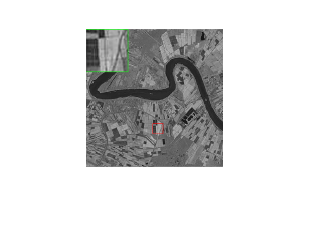

I = (imread('Capture33.PNG'));
R=I(:,:,1);
R=im2double(R);
G=I(:,:,2);
G=im2double(G);
B=I(:,:,3);
B=im2double(B);
imshow(I)

GrayImage=rgb2gray(I);
GrayImage=im2double(GrayImage);
H=entropy(GrayImage)

H = 6.9294

HFilter=[0 0 0;0 1 -1;0 0 0];
HFilterImage=imfilter(GrayImage,HFilter);
VFilter=[0 -1 0;0 1 0;0 0 0];
VFilterImage=imfilter(GrayImage,VFilter);
HFilterImage=HFilterImage.^2;
VFilterImage=VFilterImage.^2;
HV=HFilterImage+VFilterImage;
HV=HV.^(0.5);
S=sum(HV(:));
S=S/(139*137)

S = 0.0923

DeltaRG=R-G;
DeltaYB=((R+G).*0.5)-B;
MeanRG=mean(DeltaRG(:));
MeanYB=mean(DeltaYB(:));
SdRG=std(DeltaRG(:));
SdYB=std(DeltaYB(:));
C=sqrt((SdRG^2)+(SdYB^2));
C=C+0.3*sqrt((MeanRG^2)+(MeanYB^2))

C = 0.0483